Usage: choose the relevant parameters for each signal, then run the block.

Define and plot a sinusoidal signal

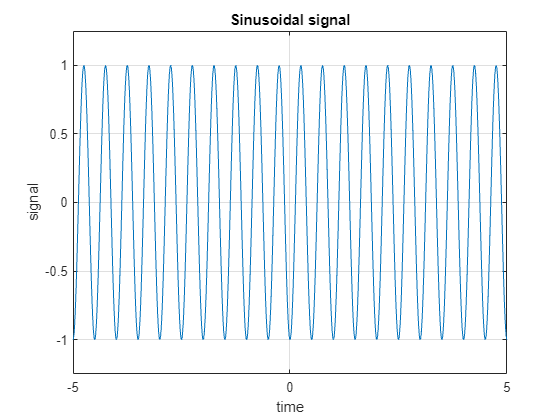

n_max = 5;
A = 1;
f = 2;
theta = pi;
offset = 0;
t = -n_max:0.01:n_max;
sinusoid = A*cos(2*pi*f*t + theta) + offset;

plot(t,sinusoid) % change to stem for discrete signals
xlabel('time');
ylabel('signal');
xlim([-n_max n_max])
ylim([-A-0.25*A A+0.25*A]) 
grid; 
title('Sinusoidal signal');

Define and plot another sinusoid

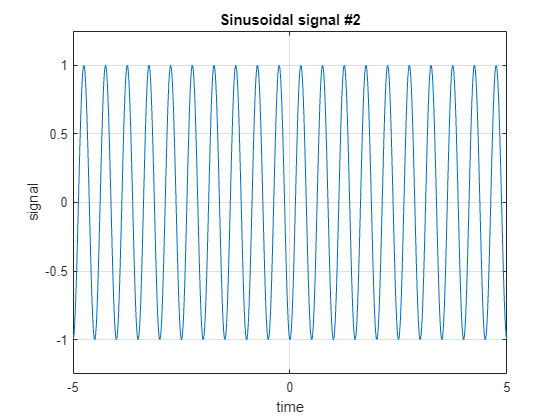

n_max_2 = 5; 
A_2 = 1;
f_2 = 2;
theta_2 = pi;
offset_2 = 0;
sinusoid_2 = A_2*cos(2*pi*f_2*t + theta_2) + offset_2;

plot(t,sinusoid_2) % change to stem for discrete signals
xlabel('time');
ylabel('signal');
xlim([-n_max_2 n_max_2])
ylim([-A_2-0.25*A_2 A_2+0.25*A_2]) 
grid; 
title('Sinusoidal signal #2');

Define and plot a square signal

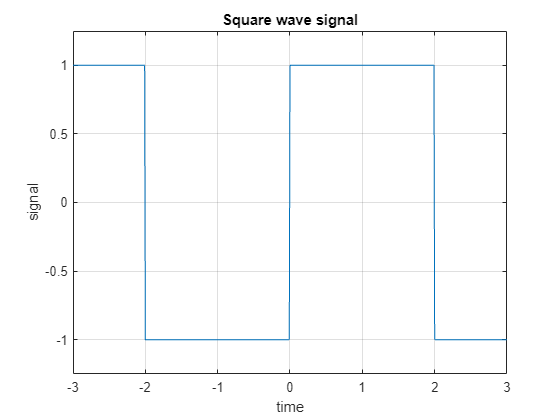

n_max_square = 3; 
A_square = 1;
f_square = 0.25;
theta_square = 0;
offset_square = 0;
t_square = -n_max:0.01:n_max;
duty_cycle = 50; 
square_wave = A_square*square(2*pi*f_square*t_square+theta_square, duty_cycle) + offset_square;

plot(t_square, square_wave);
xlabel('time');
ylabel('signal');
xlim([-n_max_square n_max_square]);
ylim([-A_square-0.25*A_square A_square+0.25*A_square]);
grid;
title('Square wave signal');

Sum signals

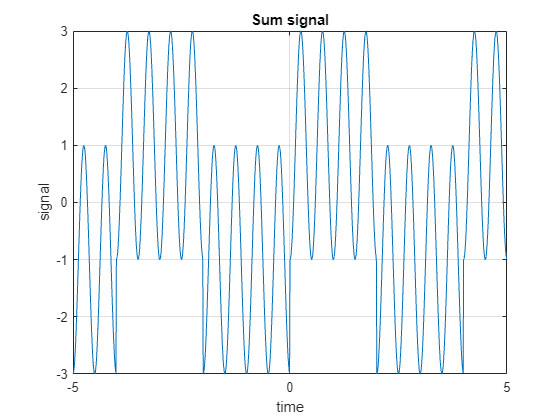

sum_signal = sinusoid + sinusoid_2 + square_wave;

plot(t, sum_signal);
xlabel('time');
ylabel('signal');
xlim([-n_max n_max]);
grid;
title('Sum signal');